load('flow_data.mat')

### 0 Degree Steering Angle

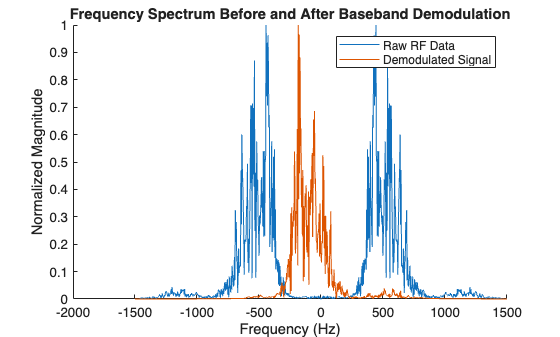

% Duplicate code but for 0 degree steering angle
rf_0 = rf(:,:,:,2);
clf;

dt = 2 * (z(2)-z(1)) / c;
t = (0:size(z, 2)-1)' * dt;
quad_demod = hilbert(rf_0);
baseband = quad_demod .* exp(-2 * 1i * pi * f0 * t);


rf_avg = mean(rf_0, [2, 3]);
demod_avg = mean(baseband, [2, 3]);

freq_rf = fftshift(abs(fft(rf_avg)));
freq_rf = freq_rf / max(freq_rf);

freq_demod = fftshift(abs(fft(demod_avg)));
freq_demod = freq_demod / max(freq_demod);

f = (-length(rf_avg) / 2:length(rf_avg)/2 - 1) * (prf / length(rf_avg));

figure;
hold on;
plot(f, freq_rf);
plot(f, freq_demod);
legend(["Raw RF Data", "Demodulated Signal"]);
title("Frequency Spectrum Before and After Baseband Demodulation");
% Add units
xlabel("Frequency (Hz)");
ylabel("Normalized Magnitude");
hold off;

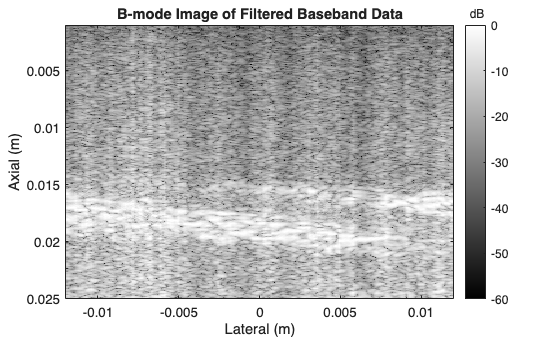

demod_double = double(baseband);
permute_data = permute(demod_double, [3 1 2]);

wf = wall_filter();
[b, a] = tf(wf);

filtered_permutated = filtfilt(b, a, permute_data);
filtered = permute(filtered_permutated, [2 3 1]);

envl_filtered_db = 20*log10(abs(filtered(:, :, frame)));
norm_envl_filtered = envl_filtered_db - max(envl_filtered_db);

imagesc(x, z, norm_envl_filtered);
cb = colorbar;
cb.Title.String = 'dB';
colormap gray;
title('B-mode Image of Filtered Baseband Data');
xlabel('Lateral (m)');
ylabel('Axial (m)');
clim([-60 0]);

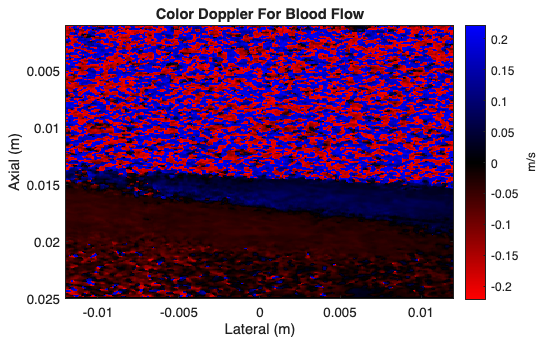

clf;
pruned_baseband = filtered(:, :, 3: 48);
prefix = -(c * prf) / (2 * 2 * pi * f0);
v_map = zeros(800, 300);
[Nd, N1, S] = size(pruned_baseband);
for i = 1:Nd - 5
    for j = 1:N1
        numerator = 0;
        denominator = 0;
        for m = i:i+5
            for n = 2:S
                numerator = numerator + (imag(pruned_baseband(m, j, n)) * real(pruned_baseband(m,j, n - 1)) - real(pruned_baseband(m,j, n)) * imag(pruned_baseband(m, j,n - 1)));
                denominator = denominator + (real(pruned_baseband(m,j, n)) * real(pruned_baseband(m,j, n - 1)) + imag(pruned_baseband(m,j, n)) * imag(pruned_baseband(m,j, n - 1)));
            end
        end
        v_map(i, j) = prefix * atan2(numerator, denominator);
    end
end

axis image;
imagesc(x, z, v_map);
clim([min(v_map(:)), max(v_map(:))]);
cb = colorbar;
cb.Label.String = 'm/s';
xlabel('Lateral (m)');
ylabel('Axial (m)');
title('Color Doppler For Blood Flow')
colormap(cmap_cf);

### -12 Degree Steering Angle

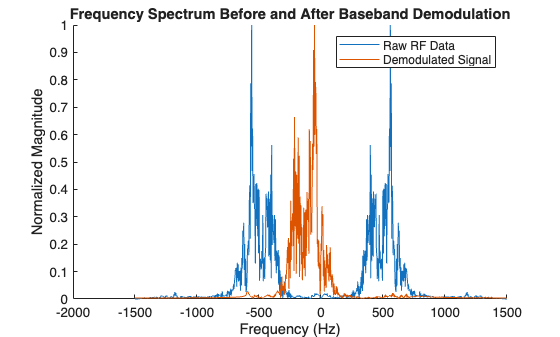

% Duplicate code for -12 degree steering angle
rf_neg_12 = rf(:,:,:,1);
clf;

dt = 2 * (z(2)-z(1)) / c;
t = (0:size(z, 2)-1)' * dt;
quad_demod = hilbert(rf_neg_12);
baseband = quad_demod .* exp(-2 * 1i * pi * f0 * t);


rf_avg = mean(rf_neg_12, [2, 3]);
demod_avg = mean(baseband, [2, 3]);

freq_rf = fftshift(abs(fft(rf_avg)));
freq_rf = freq_rf / max(freq_rf);

freq_demod = fftshift(abs(fft(demod_avg)));
freq_demod = freq_demod / max(freq_demod);

f = (-length(rf_avg) / 2:length(rf_avg)/2 - 1) * (prf / length(rf_avg));

figure;
hold on;
plot(f, freq_rf);
plot(f, freq_demod);
legend(["Raw RF Data", "Demodulated Signal"]);
title("Frequency Spectrum Before and After Baseband Demodulation");
% Add units
xlabel("Frequency (Hz)");
ylabel("Normalized Magnitude");
hold off;

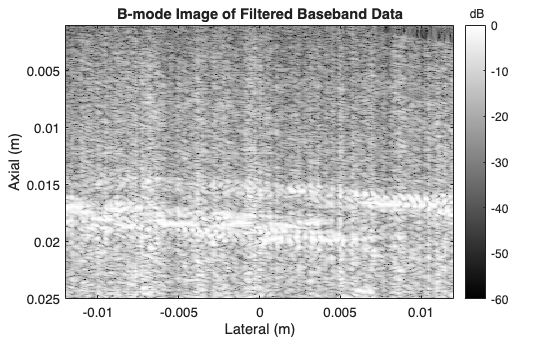

demod_double = double(baseband);
permute_data = permute(demod_double, [3 1 2]);

wf = wall_filter();
[b, a] = tf(wf);

filtered_permutated = filtfilt(b, a, permute_data);
filtered = permute(filtered_permutated, [2 3 1]);

envl_filtered_db = 20*log10(abs(filtered(:, :, frame)));
norm_envl_filtered = envl_filtered_db - max(envl_filtered_db);

imagesc(x, z, norm_envl_filtered);
cb = colorbar;
cb.Title.String = 'dB';
colormap gray;
title('B-mode Image of Filtered Baseband Data');
xlabel('Lateral (m)');
ylabel('Axial (m)');
clim([-60 0]);

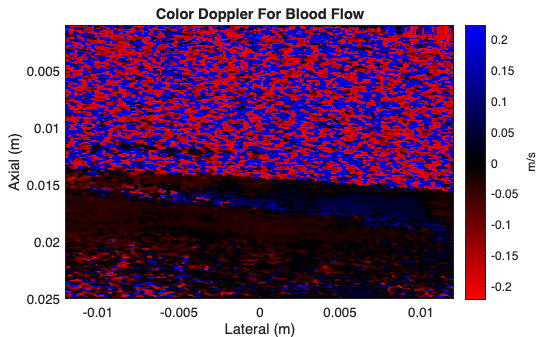

clf;
pruned_baseband = filtered(:, :, 3: 48);
prefix = -(c * prf) / (2 * 2 * pi * f0);
v_map = zeros(800, 300);
[Nd, N1, S] = size(pruned_baseband);
for i = 1:Nd - 5
    for j = 1:N1
        numerator = 0;
        denominator = 0;
        for m = i:i+5
            for n = 2:S
                numerator = numerator + (imag(pruned_baseband(m, j, n)) * real(pruned_baseband(m,j, n - 1)) - real(pruned_baseband(m,j, n)) * imag(pruned_baseband(m, j,n - 1)));
                denominator = denominator + (real(pruned_baseband(m,j, n)) * real(pruned_baseband(m,j, n - 1)) + imag(pruned_baseband(m,j, n)) * imag(pruned_baseband(m,j, n - 1)));
            end
        end
        v_map(i, j) = prefix * atan2(numerator, denominator);
    end
end

axis image;
imagesc(x, z, v_map);
clim([min(v_map(:)), max(v_map(:))]);
cb = colorbar;
cb.Label.String = 'm/s';
xlabel('Lateral (m)');
ylabel('Axial (m)');
title('Color Doppler For Blood Flow')
colormap(cmap_cf);